# Pizza Ingredient Analysis

Analyze the pizza order history data to determine the following:

- What is the typical mass of ingredients added to pizzas?

- What are the most common ingredients added to pizzas?

ImportOrders

Orders = 3085×12 table
    OrderNumber    PizzaNumber        ReceivedTime        Canceled    CancelReason        StartedTime              ReadyTime           Dough      Sauce     Cheese     Toppings                               Description                            
    ___________    ___________    ____________________    ________    ____________    ____________________    ____________________    _______    _______    _______    ________    __________________________________________________________________

         1              1         07-Jun-2021 11:10:26       0             N

Orders.IngredientsAdded = Orders.Sauce + Orders.Cheese + Orders.Toppings

Orders = 3085×13 table
    OrderNumber    PizzaNumber        ReceivedTime        Canceled    CancelReason        StartedTime              ReadyTime           Dough      Sauce     Cheese     Toppings                               Description                                IngredientsAdded
    ___________    ___________    ____________________    ________    ____________    ____________________    ____________________    _______    _______    _______    ________    __________________________________________________________________    ________________

  

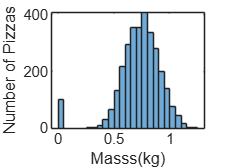


histogram(Orders.IngredientsAdded)
xlabel("Masss(kg)")
ylabel("Number of Pizzas")

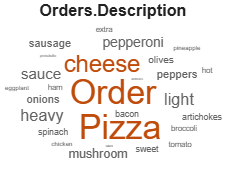

% Create wordcloud of Orders.Description
wc = wordcloud(Orders.Description);

% Add title
title("Orders.Description")